# Simulate Physical Model

## Open Model

% modelName = 'simpleHelicopter_toReduce';
modelName = 'simpleHelicopter';

open_system(modelName)

Enable or disable network trainning:

train = true;

## Generate Simulation Scenarios

Set the simulation stop time in (s)

simStopTime = 300;

Create different simulation scenarios by specifying the the heat input stairs

ascendScenarioVector = 2e3:0.5e3:5e3;
ascendDescentScenarioVector = [2e3:1e3:5e3 5e3:-1e3:2.5e3];
referenceHeatStates = {
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+155],simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+305],simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+455], simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+455], simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+605],simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+655], simStopTime}, ...
                    {ascendDescentScenarioVector,simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+150],simStopTime}, ...                      
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+300],simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+450], simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+600],simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+650], simStopTime}};

Generate the simulation scenarios and save them in MAT files

for ix=1:numel(referenceHeatStates)
    generateInputs(scenarioDir, referenceHeatStates{ix}{1},...
    referenceHeatStates{ix}{2}, ix, 'heatIn')
end

## Generate Simulink Simulation Inputs

From the generated scenarios you can create "Simulink.SimulationInputs"

load_system(modelName)
clearvars simIn
fileList = listSimInpFiles(scenarioDir);
numCases = length(fileList);
scenario = {};
simIn(1:numCases) = Simulink.SimulationInput(modelName);

for ix=1:numCases
    fileName = split(fileList{ix},'.');
    scenario{ix} = load(fileList{ix});
    aux = split(fileName{1},'_');
    scenarioSimStopTime = aux{end};
    simIn(ix) = simIn(ix).setModelParameter('StopTime', scenarioSimStopTime);
    simIn(ix) = simIn(ix).setBlockParameter([modelName '/Engine'], 'LabelModeActivechoice', 'PhysMod');
    simIn(ix) = setVariable(simIn(ix), 'Qin', scenario{ix}.stateVecRef{1}.Values.Data', ...
        'Workspace', modelName);    
    simIn(ix) = setVariable(simIn(ix),'Qin_time', scenario{ix}.stateVecRef{1}.Values.Time', ...
        'Workspace', modelName);
end

## Simulate

Simulate in parallel and save the results

out = parsim(simIn,'ShowSimulationManager','on');

[08-Nov-2023 10:57:04] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.
[08-Nov-2023 10:57:34] Starting Simulink on parallel workers...
[08-Nov-2023 10:57:51] Configuring simulation cache folder on parallel workers...
[08-Nov-2023 10:57:52] Loading model on parallel workers...
[08-Nov-2023 10:58:00] Running simulations...
[08-Nov-2023 11:03:55] Cleaning up parallel workers...


save(fullfile(simOutDir,'simOuts'),'out') 

# Prepare Data for Training

To achieve better performance the data are resampled, normalized.

## Resample simulation data

Extract data table from simulation results

for ix = 1:length(out)
    resultsTable{ix} = out(ix).logsout.extractTimetable;
end

Resample the data in seconds using [anonymous functions](https://uk.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) and [cellfun](https://uk.mathworks.com/help/matlab/ref/cellfun.html):

sampleTime = 0.1;
timeStep = out(1).tout(2)-out(1).tout(1);
batchDownSample = @(x) downsample(x,sampleTime/timeStep);
resampledData = cellfun(batchDownSample, resultsTable,'UniformOutput', false);

Reorder signals using [movevars](https://uk.mathworks.com/help/matlab/ref/table.movevars.html): 

commandSignals = {'Altitude (m)', 'Qin (kW)'};
resampledData = cellfun(@(x) movevars(x,commandSignals{1},'Before',1), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,commandSignals{2},'Before',2), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,'T3 (K)','After',8), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,'P2 (Pa)','After',8), resampledData,'UniformOutput', false);

sigNames = resampledData{1}.Properties.VariableNames;

## Visualize resampled data

Visualize table data with [stackedplot](https://uk.mathworks.com/help/matlab/ref/stackedplot.html):

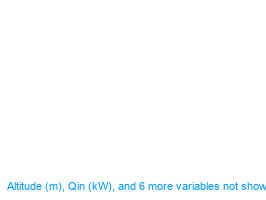

figure
stackedplot(resampledData)

## Normalize data

Concatenate the data using the [vertcat](https://uk.mathworks.com/help/matlab/ref/double.vertcat.html?searchHighlight=Vertcat&s_tid=doc_srchtitle) function:

concatDataTrain = vertcat(resampledData{:});

calculate the mean and standard deviation of the simulation data, with [mean](https://uk.mathworks.com/help/matlab/ref/mean.html) and [std](https://uk.mathworks.com/help/matlab/ref/std.html) functions

meanTrain = mean(concatDataTrain);
stdTrain = std(concatDataTrain);

save the results and clear the concatenated data

clear concatDataTrain
save("turboshaftEngine\meanTrain.mat", "meanTrain")
save("turboshaftEngine\stdTrain.mat", "stdTrain")

Apply gaussian normalization to the entire set of data.

normalize = @(x,mu,sigma) (x - mu) ./ sigma;
dataTrainNormComp = cellfun(@(x) normalize(x, meanTrain, stdTrain), resampledData, 'UniformOutput', false);


## Prepare data for training

Define the normalized inputs and the expected responses as seen below:

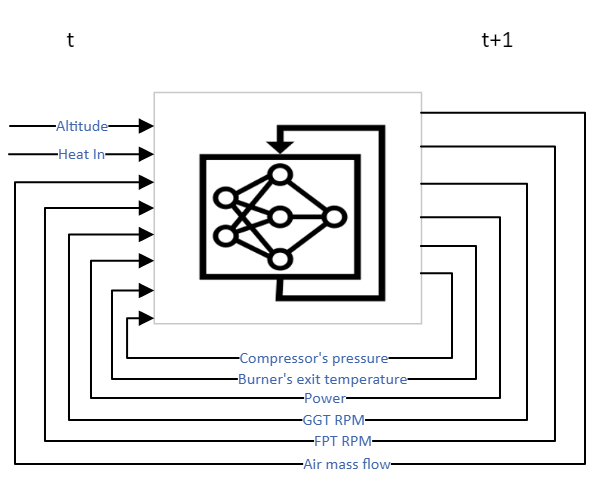

outStartIdx = length(commandSignals)+1;
inOut = @(x)[{x(1:end-1,:)} {x(2:end, outStartIdx:end)}];

aux = cellfun(inOut,dataTrainNormComp,'UniformOutput', false);

for ix=1:numel(dataTrainNormComp)
    inputTrain{ix} = table2array(aux{ix}{1});
    responseTrain{ix} = table2array(aux{ix}{2});
end
clear aux

# Train a Neural Network

## Define the inputs/outputs

Define the number of inputs and outputs of the neural network. Create respective datasets that correspond to the inputs and outputs of each timestep.

numFeatures = length(sigNames);
numResponses = length(sigNames)-length(commandSignals);
numHiddenUnits = 150;
dropoutProbability = 0.2;

## Network architecture

Choose [lstmLayer](https://uk.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.lstmlayer.html) for timeseries prediction 

layers = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    ];

## Training options

Define solver, specify learning rate and trainnig epochs

metric = rmseMetric(NormalizationFactor="batch-size");

opts = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",1e-2,...
    "MaxEpochs",500,...
    "Metrics",metric, ...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");

## Train the network with "trainnet"

Train LSTM network using the [trainnet](https://uk.mathworks.com/help/deeplearning/ref/trainnet.html) function:

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingRMSE
    _________    _____    ___________    _________    ____________    ____________
            1        1       00:00:02         0.01         0.91956          136.96
           50       50       00:00:51         0.01       0.0074427          12.322
          100      100       00:01:38         0.01       0.0043039          9.3701
          150      150       00:02:25         0.01       0.0035907          8.5586
          200      200       00:03:12         0.01       0.0032825          8.1831
          250      250       00:04:01        0.001        0.003248            8.14
          300      300       00:04:46        0.001        0.003232          8.1199
          350      350       00:05:32        0.001       0.0032318          8.1197
          400      400       00:06:17        0.001       0.0031783          8.0522
          450      450       00:07:01       0.0001       0.0031874          8.0636
    

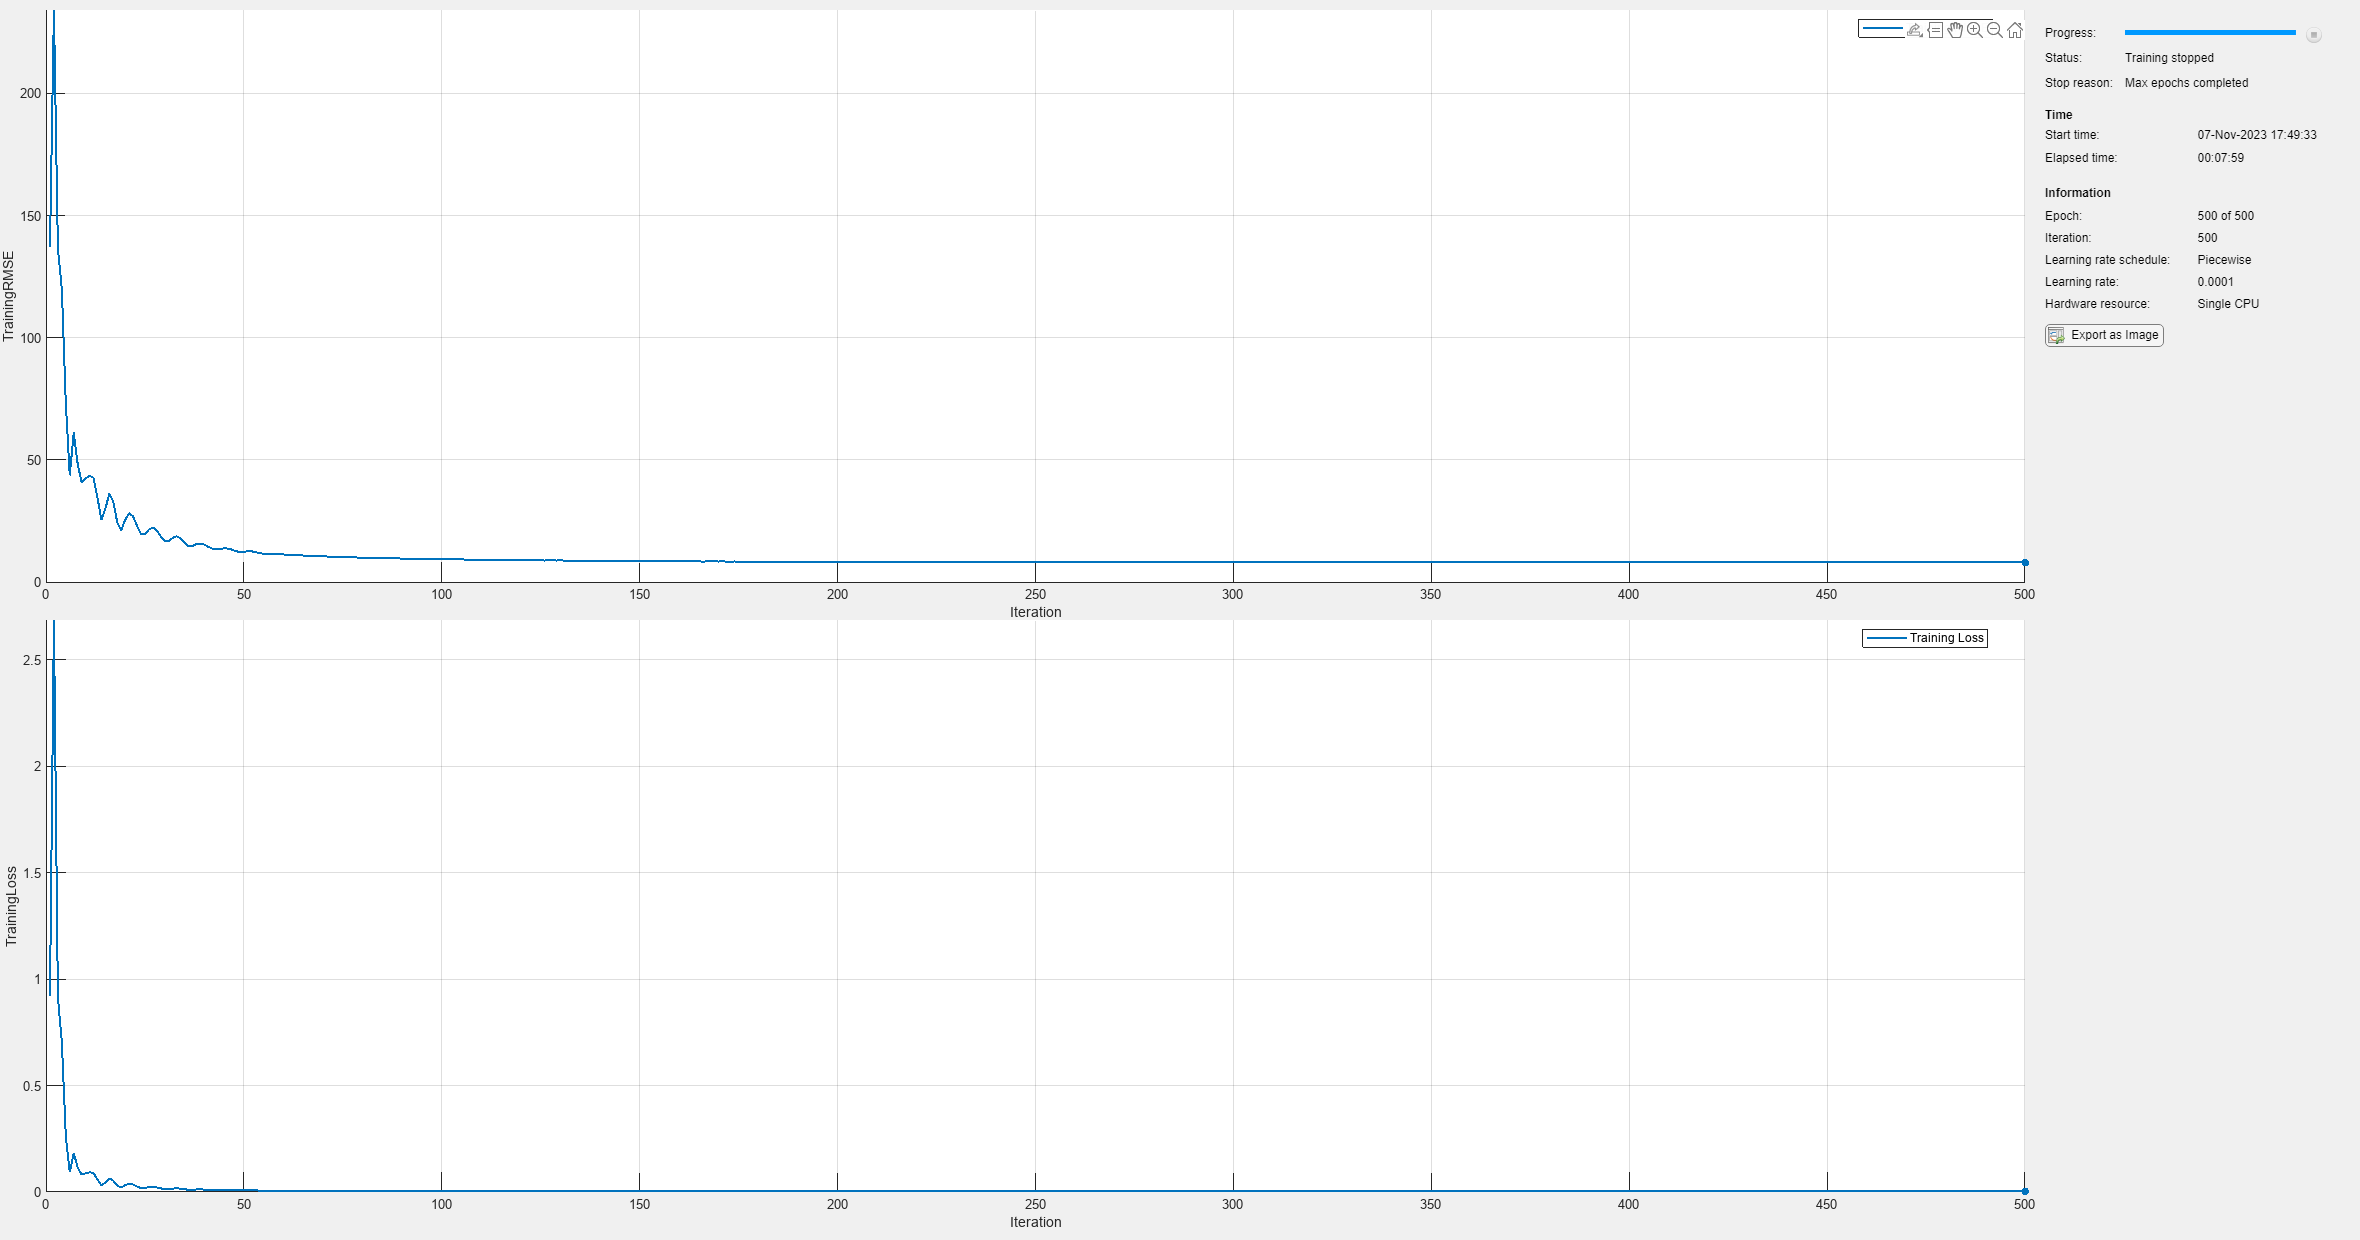

if train
    [net, ~] = trainnet(inputTrain,responseTrain,layers,'mse',opts);
    net = resetState(net);
    save("turboshaftEngine\Models\Components\turboShaftEngineLSTM_ROM\turboshaft_ROM_v5.mat","net")
end

## Train with "trainNetwork"

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |         2.28 |          2.6 |          0.0100 |
|      50 |          50 |       00:00:39 |         0.21 |      2.2e-02 |          0.0100 |
|     100 |         100 |       00:01:15 |         0.16 |      1.2e-02 |          0.0100 |
|     150 |         150 |       00:01:52 |         0.15 |      1.1e-02 |          0.0100 |
|     200 |         200 |       00:02:28 |         0.14 |      9.6e-03 |          0.0100 |
|     250 |         250 |       00:03:06 |         0.14 |      9.6e-03 |          0.0010 |
|     300 |         300 |       00:03:42 |         0.14 |      9.5

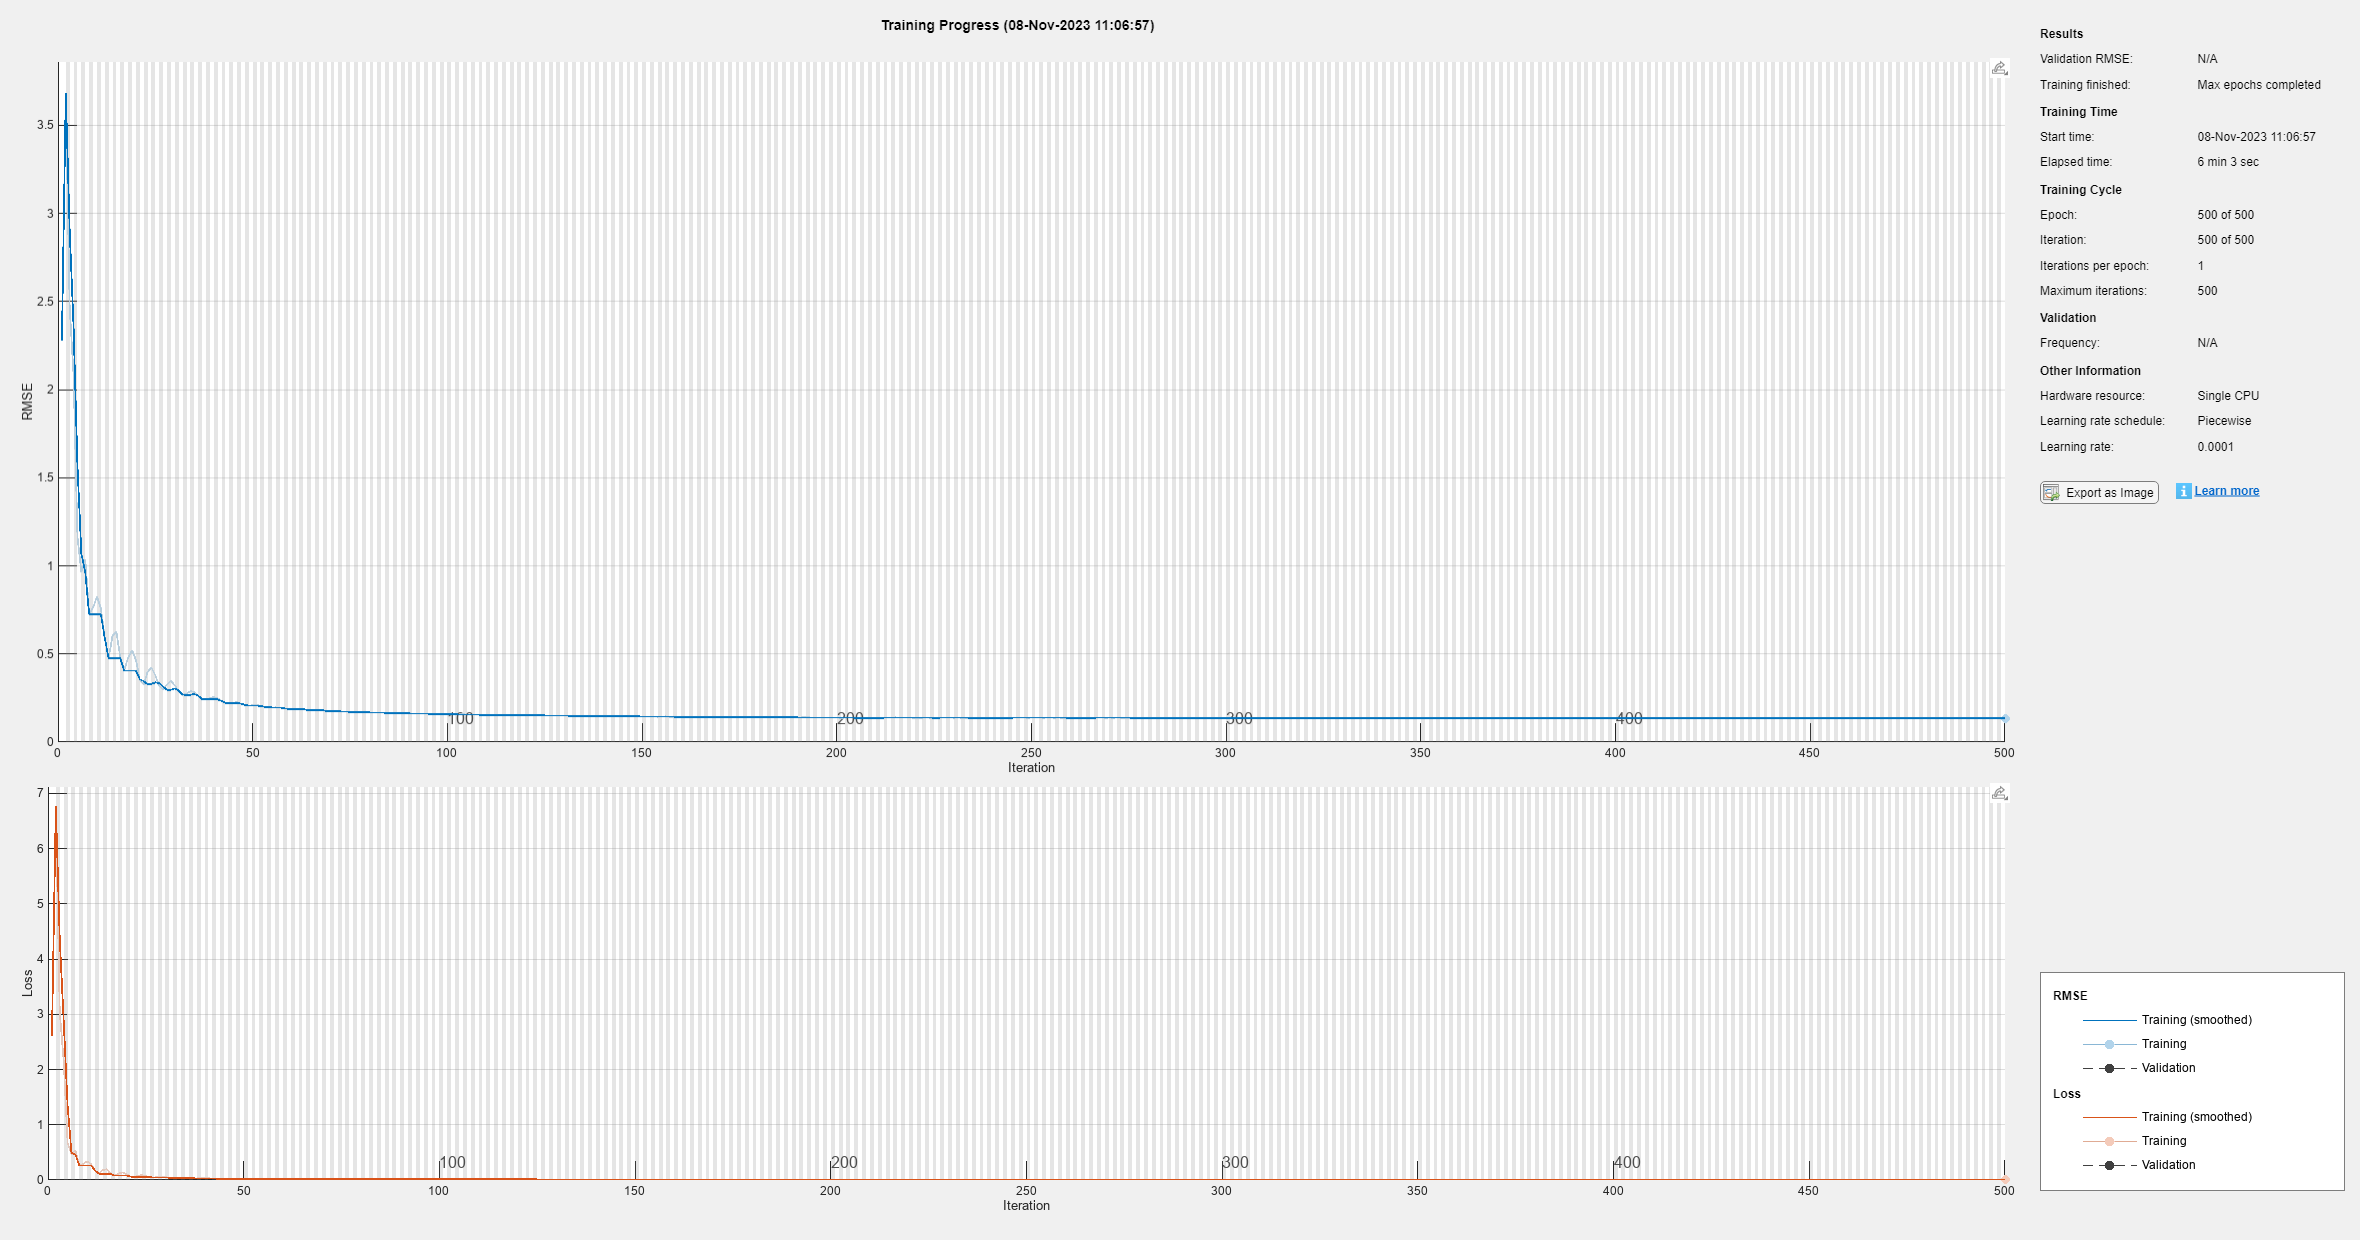

layers_TN = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    regressionLayer
    ];

opts_TN = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",1e-2,...
    "MaxEpochs",500,...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");

for ix=1:numel(dataTrainNormComp)
    XTrainSep{ix} = inputTrain{ix}';
    TTrainSep{ix} = responseTrain{ix}';
end

if train
    [net_tN, traininfo] = trainNetwork(XTrainSep,TTrainSep,layers_TN,opts_TN);
    net_tN = resetState(net_tN);
    save("turboshaftEngine\Models\Components\turboShaftEngineLSTM_ROM\turboshaft_ROM_v6.mat","net_tN")
end

## Integrate Trained LSTM Network in Simulink

You can use recurrent neural networks in simulink by using the "Stateful Predict" block 

reducedModel = 'simpleHelicopter_ROM';
open_system(reducedModel)

# Evaluate results

Compare original and reduced model rregarding their resutls and simulation performance. This comparison is on a scenario that has not been included in the trainning.

mode = 'Custom';

## Simulate the ROM

set_param([reducedModel,'/HeatIn'],'LabelModeActivechoice', mode)
romSim = sim(reducedModel);
romRunID = Simulink.sdi.Run.getLatest;

## Simulate the Physical Model

Simulate the physical model with the same simulation scenario:

referenceModel = 'simpleHelicopter_reference';
open_system(referenceModel)
set_param([referenceModel,'/HeatIn'],'LabelModeActivechoice', mode)
refSim = sim(referenceModel);
refRunID = Simulink.sdi.Run.getLatest;

## Test in Simulation Data Inspector

Define the acceptable absolute and relative tolerances

relTol = 2.5e-2;
absTol = 30;

Launch comparison on the Simulation Data Inspector

Simulink.sdi.compareRuns(refRunID.id,romRunID.id,'RelTol',relTol,'AbsTol',absTol);
Simulink.sdi.view

## Performance comparison

Compare the Simulation Metadata containing information regarding the initialization, execution and total time of the simulation.

The timing info for the reference simulation

refSim.SimulationMetadata.TimingInfo;
ref.init = refSim.SimulationMetadata.TimingInfo.InitializationElapsedWallTime;
ref.execution = refSim.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime;
ref.total = refSim.SimulationMetadata.TimingInfo.TotalElapsedWallTime;
baseline = [ref.init ref.execution ref.total];

The timing info for the ROM model

romSim.SimulationMetadata.TimingInfo;
rom.init = romSim.SimulationMetadata.TimingInfo.InitializationElapsedWallTime;
rom.execution = romSim.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime;
rom.total = romSim.SimulationMetadata.TimingInfo.TotalElapsedWallTime;
reduced = [rom.init rom.execution rom.total];

Compare performance:

categories = categorical({'Initialization','Execution','Total'});
timereduction = (baseline-reduced)./baseline.*100;
bar(categories, timereduction, 0.3)
ylabel('Time reduction (%)')
grid('on')

# Real-Time Simulation

Use Simulink Real-Time to simulate the model in real time:

open_system('simpleHelicopter_ROM_realTime')

 Let's take-off !